# 1.3.02. Программирование. Цикл `for`

**Практическое занятие**

Найдите сумму ряда c помощью цикла `for.`


$$\sum_{k=0}^n {\left(-1\right)}^{k-1} \frac{2^{2k-1} x^{2k} }{\left(2k\right)!},\;x\in \left\lbrack 0,1\right\rbrack$$


Входными данными являются значение `x` из области сходимости ряда и количество повторов `n`. После вычисления суммы вывести в виде текста следующие данные: x, число итераций, сумму ряда и "точное" значение при $n=\infty$, которое рассчитывается по точной формуле. В графическом окне в одной координатной плоскости построить графики суммы ряда и членов ряда `ak` в зависимости от номера повтора или номера члена ряда k.

Точная формула:


$$\sum_{k=0}^n {\left(-1\right)}^{k-1} \frac{2^{2k-1} x^{2k} }{\left(2k\right)!}=\frac{-\mathit{cos}\left(2x\right)}{2}$$


x = 0.9; % [0,1]
n = 5;

summa = 0;
ak = 0;
for k = 0:n
    ak(k+1) = (-1)^(k-1)*2^(2*k-1)*x^(2*k)/factorial(2*k);
    summa(k+2) = summa(k+1) + ak(k+1);
end
summa = summa(2:end);
 
m=-cos(2*x)/2;
disp(['x=',num2str(x)])

x=0.9


disp(['n=',num2str(n)])

n=5


disp(['summa=',num2str(summa)])

summa=-0.5        0.31      0.0913     0.11492     0.11355      0.1136


disp(['abssuma=',num2str(m)])

abssuma=0.1136


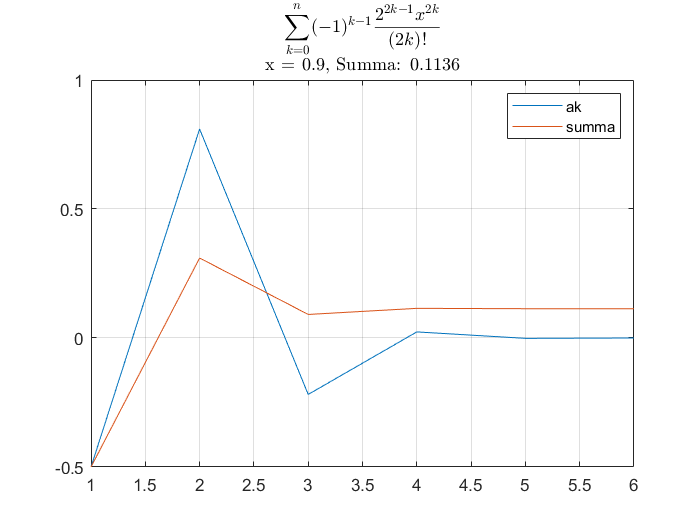

plot(ak), hold on, grid on, plot(summa), hold off
legend('ak','summa') 
 
title( {['$$\sum_{k=0}^{n}(-1)^{k-1}\frac{2^{2k-1}x^{2k}}{(2k)!}$$'];...
    ['x = ', num2str(x), ',  Summa: ', num2str(summa(end))]},...
    'Interpreter','latex')